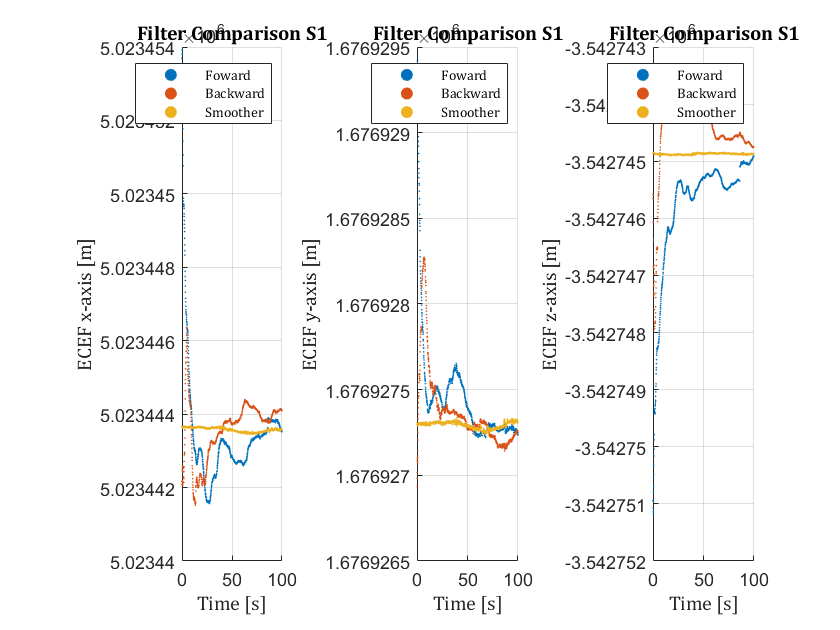

fwd_s1 = readmatrix("C:\Users\avall\Downloads\ELEVATION MASK PLOTS\fwd_sensor1.csv");
fwd_s2 = readmatrix("C:\Users\avall\Downloads\ELEVATION MASK PLOTS\fwd_sensor2.csv");
fwd_s3 = readmatrix("C:\Users\avall\Downloads\ELEVATION MASK PLOTS\fwd_sensor3.csv");


bwd_s1 = readmatrix("C:\Users\avall\Downloads\ELEVATION MASK PLOTS\bckwd_sensor1.csv");
bwd_s2 = readmatrix("C:\Users\avall\Downloads\ELEVATION MASK PLOTS\bckwd_sensor2.csv");
bwd_s3 = readmatrix("C:\Users\avall\Downloads\ELEVATION MASK PLOTS\bckwd_sensor3.csv");


comb_s1 = readmatrix("C:\Users\avall\Downloads\ELEVATION MASK PLOTS\smoother_sensor1.csv");
comb_s2 = readmatrix("C:\Users\avall\Downloads\ELEVATION MASK PLOTS\smoother_sensor2.csv");
comb_s3 = readmatrix("C:\Users\avall\Downloads\ELEVATION MASK PLOTS\smoother_sensor3.csv");
%% sensor 1 extract 
x_fwd_s1 = fwd_s1(1:1000,2);
y_fwd_s1 = fwd_s1(1:1000,3) ; 
z_fwd_s1 = fwd_s1(1:1000,4);

x_bwd_s1 = bwd_s1(1:1000,2);
y_bwd_s1 = bwd_s1(1:1000,3) ; 
z_bwd_s1 = bwd_s1(1:1000,4);

x_comb_s1 = comb_s1(1:1000,2);
y_comb_s1 = comb_s1(1:1000,3) ; 
z_comb_s1 = comb_s1(1:1000,4);
%% sensor 2 extract 
x_fwd_s2 = fwd_s2(1:1000,2);
y_fwd_s2 = fwd_s2(1:1000,3);  
z_fwd_s2 = fwd_s2(1:1000,4);

x_bwd_s2 = bwd_s2(1:1000,2);
y_bwd_s2 = bwd_s2(1:1000,3) ; 
z_bwd_s2 = bwd_s2(1:1000,4);

x_comb_s2 = comb_s2(1:1000,2);
y_comb_s2 = comb_s2(1:1000,3) ; 
z_comb_s2 = comb_s2(1:1000,4);

%% sensor 3 extract 
x_fwd_s3 = fwd_s3(1:1000,2);
y_fwd_s3 = fwd_s3(1:1000,3);  
z_fwd_s3 = fwd_s3(1:1000,4);

x_bwd_s3 = bwd_s3(1:1000,2);
y_bwd_s3 = bwd_s3(1:1000,3) ; 
z_bwd_s3 = bwd_s3(1:1000,4);

x_comb_s3 = comb_s3(1:1000,2);
y_comb_s3 = comb_s3(1:1000,3) ; 
z_comb_s3 = comb_s3(1:1000,4);

%% sensor 1 plot

sz = 1;
n=0:0.1:99.9;


figure()
subplot(1,3,1)
scatter(n,x_fwd_s1, sz, 'filled')
hold on
scatter(n,x_bwd_s1, sz, 'filled')
hold on
scatter(n,x_comb_s1, sz, 'filled')
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'ECEF x-axis [m]'},'FontSize',8,'FontName','Cambria');
title({'Filter Comparison S1'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'Foward','Backward','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(1,3,2)
scatter(n,y_fwd_s1, sz, 'filled')
hold on
scatter(n,y_bwd_s1, sz, 'filled')
hold on
scatter(n,y_comb_s1, sz, 'filled')
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'ECEF y-axis [m]'},'FontSize',8,'FontName','Cambria');
title({'Filter Comparison S1'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'Foward','Backward','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(1,3,3)
scatter(n,z_fwd_s1, sz, 'filled')
hold on
scatter(n,z_bwd_s1, sz, 'filled')
hold on
scatter(n,z_comb_s1, sz, 'filled')
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'ECEF z-axis [m]'},'FontSize',8,'FontName','Cambria');
title({'Filter Comparison S1'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'Foward','Backward','Smoother'},'FontSize',7,'FontName','Cambria')

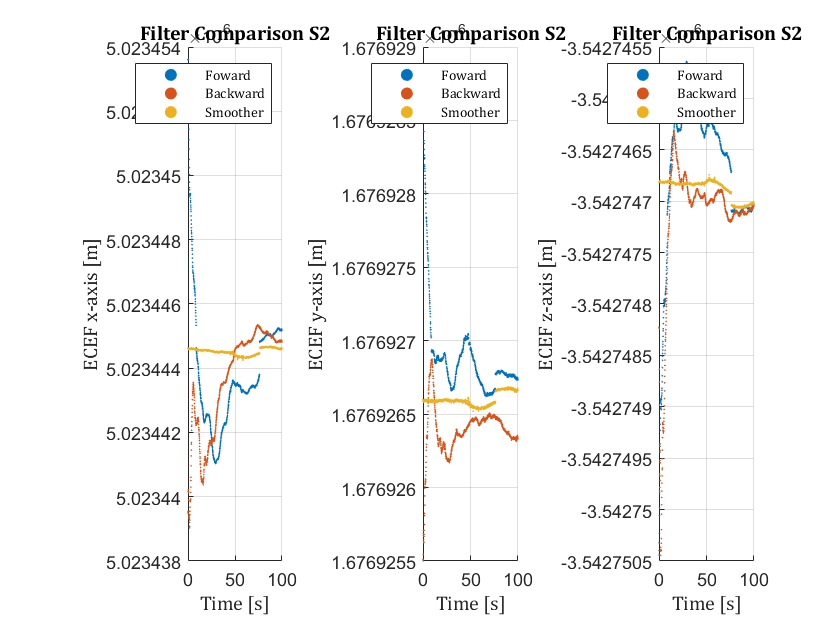



%% sensor 2 plot

sz = 1;
n=0:0.1:99.9;


figure()
subplot(1,3,1)
scatter(n,x_fwd_s2, sz, 'filled')
hold on
scatter(n,x_bwd_s2, sz, 'filled')
hold on
scatter(n,x_comb_s2, sz, 'filled')
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'ECEF x-axis [m]'},'FontSize',8,'FontName','Cambria');
title({'Filter Comparison S2'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'Foward','Backward','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(1,3,2)
scatter(n,y_fwd_s2, sz, 'filled')
hold on
scatter(n,y_bwd_s2, sz, 'filled')
hold on
scatter(n,y_comb_s2, sz, 'filled')
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'ECEF y-axis [m]'},'FontSize',8,'FontName','Cambria');
title({'Filter Comparison S2'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'Foward','Backward','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(1,3,3)
scatter(n,z_fwd_s2, sz, 'filled')
hold on
scatter(n,z_bwd_s2, sz, 'filled')
hold on
scatter(n,z_comb_s2, sz, 'filled')
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'ECEF z-axis [m]'},'FontSize',8,'FontName','Cambria');
title({'Filter Comparison S2'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'Foward','Backward','Smoother'},'FontSize',7,'FontName','Cambria')

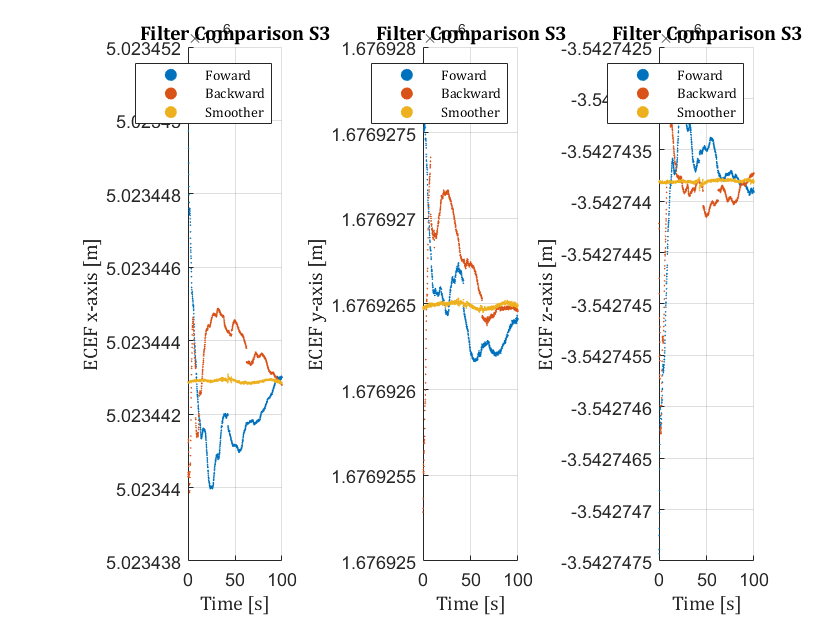


%% sensor 3 plot

sz = 1;
n=0:0.1:99.9;


figure()
subplot(1,3,1)
scatter(n,x_fwd_s3, sz, 'filled')
hold on
scatter(n,x_bwd_s3, sz, 'filled')
hold on
scatter(n,x_comb_s3, sz, 'filled')
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'ECEF x-axis [m]'},'FontSize',8,'FontName','Cambria');
title({'Filter Comparison S3'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'Foward','Backward','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(1,3,2)
scatter(n,y_fwd_s3, sz, 'filled')
hold on
scatter(n,y_bwd_s3, sz, 'filled')
hold on
scatter(n,y_comb_s3, sz, 'filled')
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'ECEF y-axis [m]'},'FontSize',8,'FontName','Cambria');
title({'Filter Comparison S3'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'Foward','Backward','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(1,3,3)
scatter(n,z_fwd_s3, sz, 'filled')
hold on
scatter(n,z_bwd_s3, sz, 'filled')
hold on
scatter(n,z_comb_s3, sz, 'filled')
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'ECEF z-axis [m]'},'FontSize',8,'FontName','Cambria');
title({'Filter Comparison S3'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'Foward','Backward','Smoother'},'FontSize',7,'FontName','Cambria')